# Sample Problem 15.12

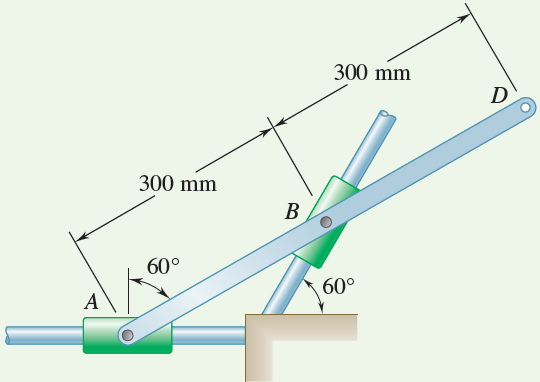

## Given                                          Find


$$V_a =0\ldotp 9\;\frac{m}{s\;}\;\mathrm{to}\;\mathrm{the}\;\mathrm{right}\;$$
                                      
$$\alpha_{\mathrm{AB}} ,a_B$$



$$\omega =3\;\frac{\mathrm{rad}}{s}$$


## Initialize known quantities

va = 0.9; % velocity of A
aa = 0; % acceleration of A
theta = 30 * pi / 180; % angle of bar to the horizontal
w = 3; % angular velocity of system

## Model and Analyze System

Write the left hand side in terms of **i** and **j**


$${\mathit{\mathbf{a}}}_B \;=\;a_{\mathrm{Bx}} \mathbf{i}\;+\;a_{\mathrm{By}} \mathit{\mathbf{j}}\;=\;a_B \cos \left(60\right)\mathit{\mathbf{i}}\;+a_B \sin \left(60\right)\mathit{\mathbf{j}}$$


sympref('FloatingPointOutput',true); % symbolic math setting
ab = sym('ab');
lhs = ab*[cosd(60); sind(60); 0] % left hand side coefficients

$$lhs = \left(\begin{array}{c} 0.5000\,\mathrm{ab}\\ 0.8660\,\mathrm{ab}\\ 0 \end{array}\right)$$

Split the right hand side into discrete components


$${\mathit{\mathbf{a}}}_A$$


aa_term = aa * [1; 0; 0];


$$\alpha \;\times \;{\mathit{\mathbf{r}}}_{\frac{B}{A}} =\alpha \mathit{\mathbf{k}}\times \left\lbrack 0\ldotp 3\cos \left(\theta \right)\mathit{\mathbf{i}}\;+\;0\ldotp 3\sin \left(\theta \right)\mathit{\mathbf{j}}\right\rbrack$$


alpha = sym('alpha');
k = [0; 0; 1];
rab = [0.3*cos(theta); 0.3*sin(theta); 0];
alpha_term = cross(alpha*k,rab);


$$\omega^2 \;{\mathit{\mathbf{r}}}_{\frac{B}{A}} =\omega^2 \;\left(0\ldotp 3\cos \left(\theta \right)\mathit{\mathbf{i}}\;+\;0\ldotp 3\sin \left(\theta \right)\mathit{\mathbf{j}}\right)$$


omega_term = w^2*rab;

Combine all three terms to produce the right hand side

rhs = aa_term + alpha_term - omega_term % rhs of eq

$$rhs = \left(\begin{array}{c} -0.1500\,\alpha -2.3383\\ 0.2598\,\alpha -1.3500\\ 0 \end{array}\right)$$

We then have the following equations

lhs(1:2) == rhs(1:2)

$$ans = \left(\begin{array}{c} 0.5000\,\mathrm{ab}=-0.1500\,\alpha -2.3383\\ 0.8660\,\mathrm{ab}=0.2598\,\alpha -1.3500 \end{array}\right)$$

We can solve these using the *solve* function

S = solve(lhs(1:2)==rhs(1:2))

S = struct with fields:
       ab: [1×1 sym]
    alpha: [1×1 sym]


S.ab

$$ans = -3.1177$$

S.alpha

$$ans = -5.1962$$